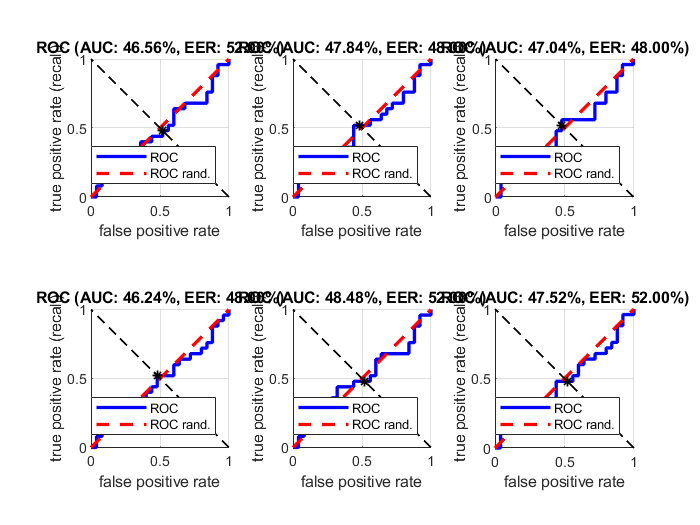

Error using figure
Argument must be a Figure object or a positive integer.

train_features = getImagesFeatures('cdvs_thumbnails\', "sift");
file = load('MPEG.CDVS\fnames_all-mp_fid-nmp_fid-n_mp-n_nmp.mat');

k_dim=[24, 48];
num_clus=[32,64,96];

for i=1:length(k_dim)
    for j=1:length(num_clus)
        kd = k_dim(i);
        k = num_clus(j);
        
        [fv_m, B] = getFisherVectorModel(train_features', kd, k);

        match_fid = file.mp_fid(1:25,:);
        no_match_fid = file.nmp_fid(1:25,:);
        
        matches = getDistances(match_fid, "sift", "fv", kd, k, fv_m);
        non_matches = getDistances(no_match_fid, "sift", "fv", kd, k, fv_m);
        
        train_num = 25;
        labels = [ones(1, train_num) -ones(1,train_num)];
        scores = [matches non_matches];
        
        nexttile
        vl_roc(labels, scores);
    end
end